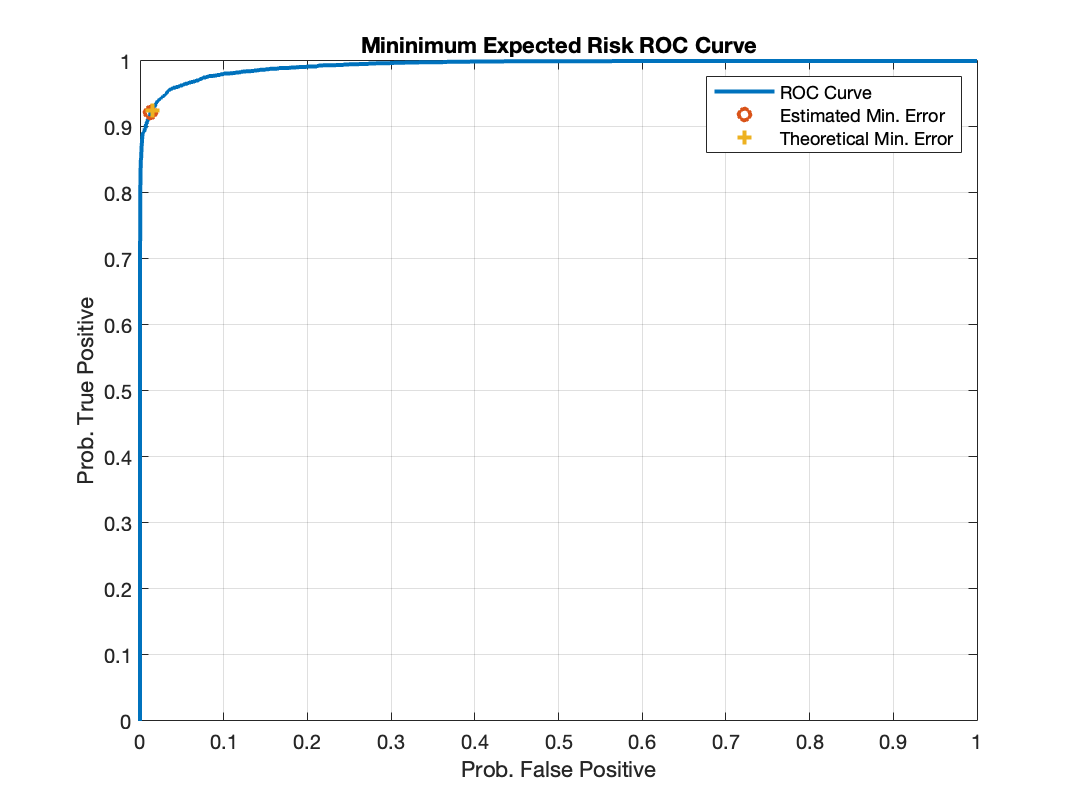

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
%EECE5644 Spring 2022
%Homework #1
%Problem #1
%Significant parts of this code were derived from the following sources 
%
%
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
clear all; close all;

%Initialize Parameters and Generate Data
N = 10000;  %Number of data points
n = 4;        %Dimensions of data
p0 = 0.7;  %Prior for label 0
p1 = 0.3;  %Prior for label 1
u = rand(1,N)>=p0; %Determine posteriors

%Create appropriate number of data points from each distribution
N0 = length(find(u==0));
N1 = length(find(u==1));
N = N0 + N1;
label=[zeros(1,N0) ones(1,N1)];

%Parameters for two classes
%mu: mean vector
%singma: covariance matrix
mu0 = [-1;-1;-1;-1];
Sigma0 = [2,-0.5,0.3,0;
        -0.5,1,-0.5,0;
        0.3,-0.5,1,0;
        0,0,0,2];
mu1 = [1;1;1;1];
Sigma1 = [1,0.3,-0.2,0;
        0.3,2,0.3,0;
        -0.2,0.3,1,0;
        0,0,0,3];

%Generate data as prescribed in assignment description
r0 = mvnrnd(mu0, Sigma0, N0);
r1 = mvnrnd(mu1, Sigma1, N1);

%Combine data from each distribution into a single dataset
x=zeros(N,n);
x(label==0,:)=r0;
x(label==1,:)=r1;

%Part A: ERM Classification with True Knowledge
discScore=log(evalGaussian(x',mu1,Sigma1)./evalGaussian(x',mu0,Sigma0)); 
sortDS=sort(discScore);

%Generate vector of gammas for parametric sweep 
logGamma=[min(discScore)-eps sort(discScore)+eps];
for ind=1:length(logGamma)
    decision=discScore>logGamma(ind);
    Num_pos(ind)=sum(decision);
    pFP(ind)=sum(decision==1 & label==0)/N0;
    pTP(ind)=sum(decision==1 & label==1)/N1;
    pFN(ind)=sum(decision==0 & label==1)/N1;
    pTN(ind)=sum(decision==0 & label==0)/N0;
    %Two ways to make sure I did it right
    pFE(ind)=(sum(decision==0 & label==1) + sum(decision==1 & label==0))/N; 
    pFE2(ind)=(pFP(ind)*N0 + pFN(ind)*N1)/N;
end

%Calculate Theoretical Minimum Error
logGamma_ideal=log(p0/p1); 
decision_ideal=discScore>logGamma_ideal; 
pFP_ideal=sum(decision_ideal==1 & label==0)/N0; 
pTP_ideal=sum(decision_ideal==1 & label==1)/N1; 
pFE_ideal=(pFP_ideal*N0+(1-pTP_ideal)*N1)/(N0+N1);

%Estimate Minimum Error
%If multiple minimums are found choose the one closest to the theoretical %minimum
[min_pFE, min_pFE_ind]=min(pFE);
if length(min_pFE_ind)>1
    [~,minDistTheory_ind]=min(abs(logGamma(min_pFE_ind)-logGamma_ideal));
    min_pFE_ind=min_pFE_ind(minDistTheory_ind);
end

%Find minimum gamma and corresponding false and true positive rates
minGAMMA=exp(logGamma(min_pFE_ind)); 
min_FP=pFP(min_pFE_ind); 
min_TP=pTP(min_pFE_ind);

%Plot
figure;
plot(pFP,pTP,'DisplayName','ROC Curve','LineWidth',2);
hold all;
plot(min_FP,min_TP,'o','DisplayName','Estimated Min. Error','LineWidth',2); 
plot(pFP_ideal,pTP_ideal,'+','DisplayName',...
'Theoretical Min. Error','LineWidth',2); 
xlabel('Prob. False Positive'); 
ylabel('Prob. True Positive'); 
title('Mininimum Expected Risk ROC Curve'); 
legend 'show';
grid on; box on;

fprintf('Theoretical: Gamma=%1.2f, Error=%1.2f%%\n',...
    exp(logGamma_ideal),100*pFE_ideal);

Theoretical: Gamma=2.33, Error=3.32%


fprintf('Estimated: Gamma=%1.2f, Error=%1.2f%%\n',minGAMMA,100*min_pFE);

Estimated: Gamma=2.78, Error=3.26%


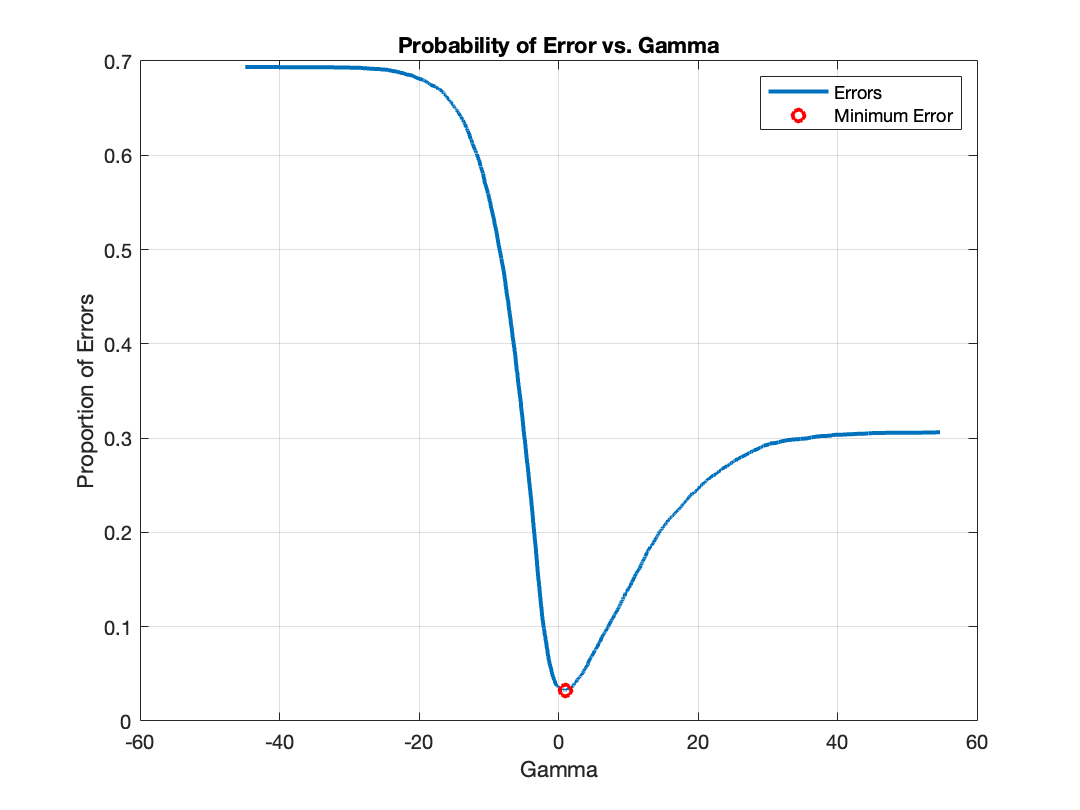


figure; 
plot(logGamma,pFE,'DisplayName','Errors','LineWidth',2); 
hold on;
plot(logGamma(min_pFE_ind),pFE(min_pFE_ind),...
'ro','DisplayName','Minimum Error','LineWidth',2); 
xlabel('Gamma');
ylabel('Proportion of Errors');
title('Probability of Error vs. Gamma');
grid on;
legend 'show';

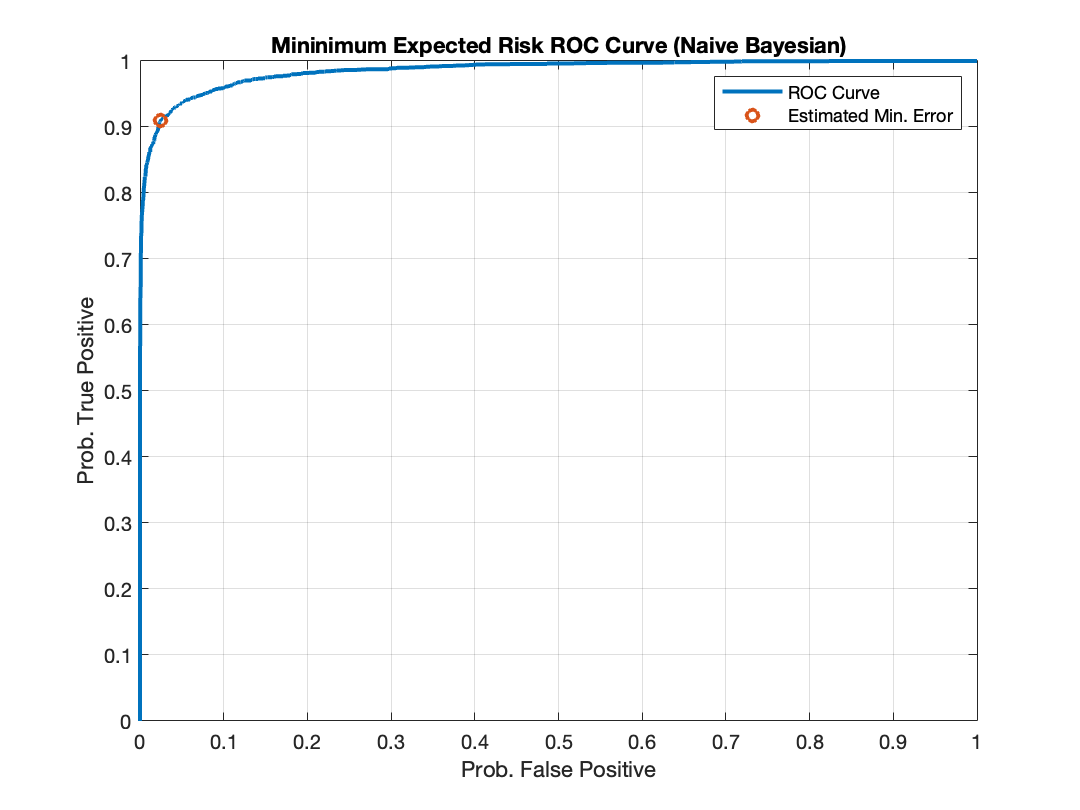



%Part 2: Naive Bayesian Classifier
Sigma_NB=eye(4);    %Assumed covariance
%Generate data to illustrate assumptions
r0_NB = mvnrnd(mu0, Sigma_NB, N0);
r1_NB = mvnrnd(mu1, Sigma_NB, N1);

%Evaluate for different gammas
discScore_NB=...
    log(evalGaussian(x' ,mu1,Sigma_NB)./evalGaussian(x' ,mu0,Sigma_NB));
logGamma_NB=[min(discScore_NB)-0.1 sort(discScore_NB)+0.1];
for ind=1:length(logGamma_NB) 
    decision=discScore_NB>logGamma_NB(ind);
    Num_pos_NB(ind)=sum(decision); 
    pFP_NB(ind)=sum(decision==1 & label==0)/N0; 
    pTP_NB(ind)=sum(decision==1 & label==1)/N1; 
    pFN_NB(ind)=sum(decision==0 & label==1)/N1; 
    pTN_NB(ind)=sum(decision==0 & label==0)/N0;

    pFE_NB(ind)=(sum(decision==0 & label==1) + sum(decision==1 & label==0))/(N0+N1);
    pFE2_NB(ind)=pFP(ind)*p0+pFN(ind)*p1;
end

%Estimated Minimum Error
[min_pFE_NB, min_pFE_ind_NB]=min(pFE_NB); 
minGAMMA_NB=exp(logGamma(min_pFE_ind_NB)); 
min_FP_NB=pFP_NB(min_pFE_ind_NB); 
min_TP_NB=pTP_NB(min_pFE_ind_NB);

%Plot Results
figure;
plot(pFP_NB,pTP_NB,'DisplayName','ROC Curve','LineWidth',2); hold all;
plot(min_FP_NB,min_TP_NB,'o','DisplayName',...
    'Estimated Min. Error','LineWidth',2);
xlabel('Prob. False Positive');
ylabel('Prob. True Positive');
title('Mininimum Expected Risk ROC Curve (Naive Bayesian)'); 
legend 'show';
grid on; box on;

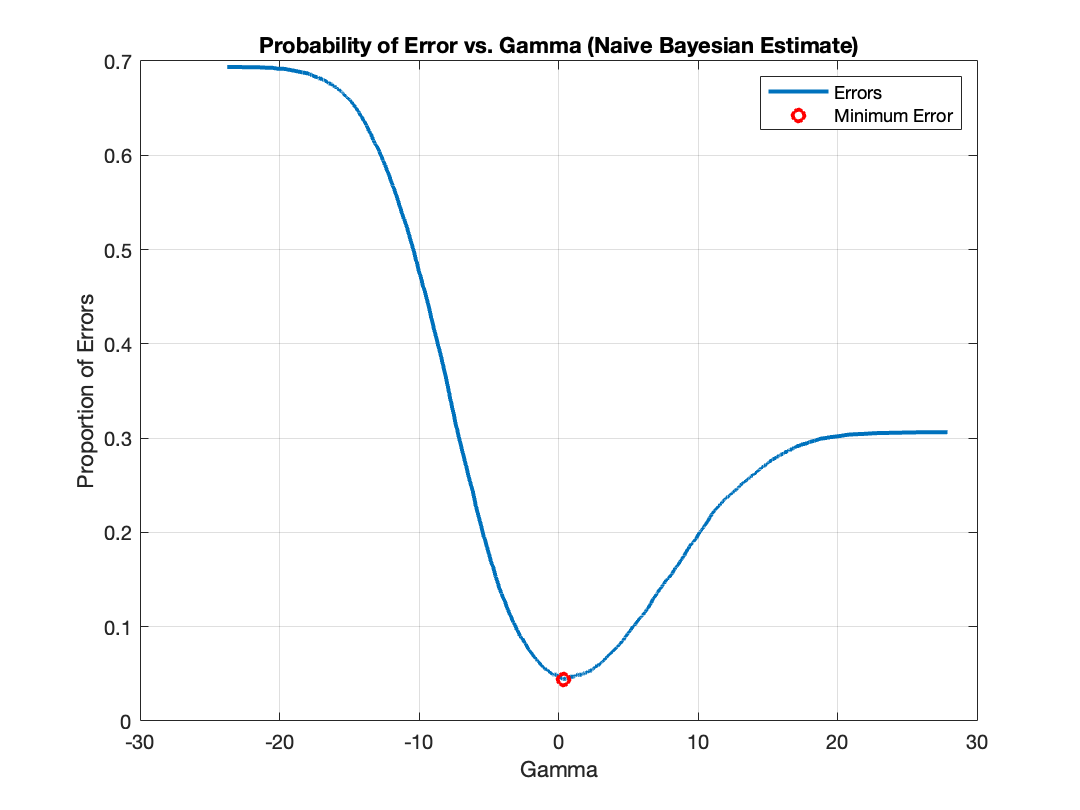


figure; 
plot(logGamma_NB,pFE_NB,'DisplayName','Errors','LineWidth',2); 
hold on; 
plot(logGamma_NB(min_pFE_ind_NB),pFE_NB(min_pFE_ind_NB),'ro',...
    'DisplayName','Minimum Error','LineWidth',2); 
xlabel('Gamma');
ylabel('Proportion of Errors');
title('Probability of Error vs. Gamma (Naive Bayesian Estimate)') 
grid on;
legend 'show';

fprintf('Estimated for NB: Gamma=%1.2f, Error=%1.2f%%\n', minGAMMA_NB,100*min_pFE_NB);

Estimated for NB: Gamma=1.84, Error=4.45%


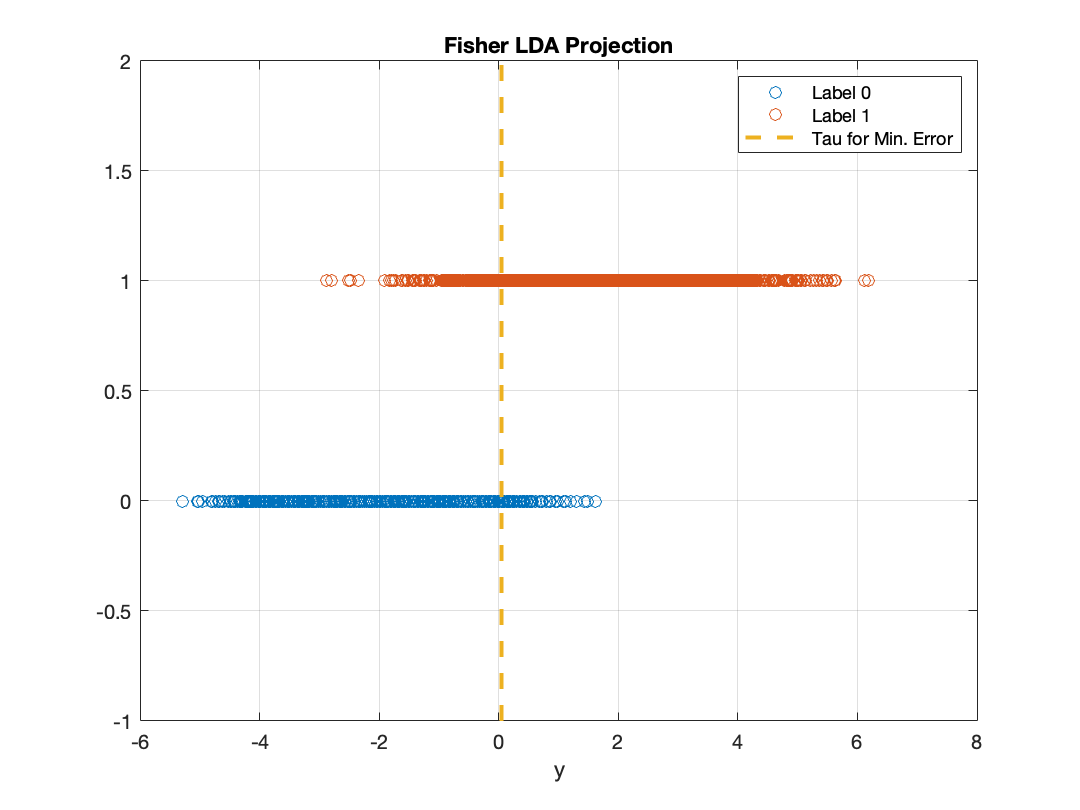


%Part 3: Fisher LDA
%Compute Sample Mean and covariances
mu0_hat=mean(r0)';
mu1_hat=mean(r1)';
Sigma0_hat=cov(r0);
Sigma1_hat=cov(r1);

%Compute scatter matrices
Sb=(mu0_hat-mu1_hat)*(mu0_hat-mu1_hat)'; 
Sw=Sigma0_hat+Sigma1_hat;

%Eigen decompostion to generate WLDA
[V,D]=eig(inv(Sw)*Sb);
[~,ind]=max(diag(D));
w=V(:,ind);
y=w'*x';
w=sign(mean(y(find(label==1))-mean(y(find(label==0)))))*w; 
y=sign(mean(y(find(label==1))-mean(y(find(label==0)))))*y;

%Evaluate for different taus
tau=[min(y)-0.1 sort(y)+0.1];

for ind=1:length(tau)
    decision=y>tau(ind); 
    Num_pos_LDA(ind)=sum(decision); 
    pFP_LDA(ind)=sum(decision==1 & label==0)/N0; 
    pTP_LDA(ind)=sum(decision==1 & label==1)/N1; 
    pFN_LDA(ind)=sum(decision==0 & label==1)/N1; 
    pTN_LDA(ind)=sum(decision==0 & label==0)/N0;
    pFE_LDA(ind)=(sum(decision==0 & label==1) + sum(decision==1 & label==0))/(N0+N1);
end

%Estimated Minimum Error
[min_pFE_LDA, min_pFE_ind_LDA]=min(pFE_LDA); 
minTAU_LDA=tau(min_pFE_ind_LDA); 
min_FP_LDA=pFP_LDA(min_pFE_ind_LDA); 
min_TP_LDA=pTP_LDA(min_pFE_ind_LDA);

%Plot results
figure; 
plot(y(label==0),zeros(1,N0),'o','DisplayName','Label 0'); 
hold all; 
plot(y(label==1),ones(1,N1),'o','DisplayName','Label 1'); 
ylim([-1 2]); 
plot(repmat(tau(min_pFE_ind_LDA),1,2),ylim,'--',...
    'DisplayName','Tau for Min. Error','LineWidth',2); grid on;
xlabel('y');
title('Fisher LDA Projection');
legend 'show';

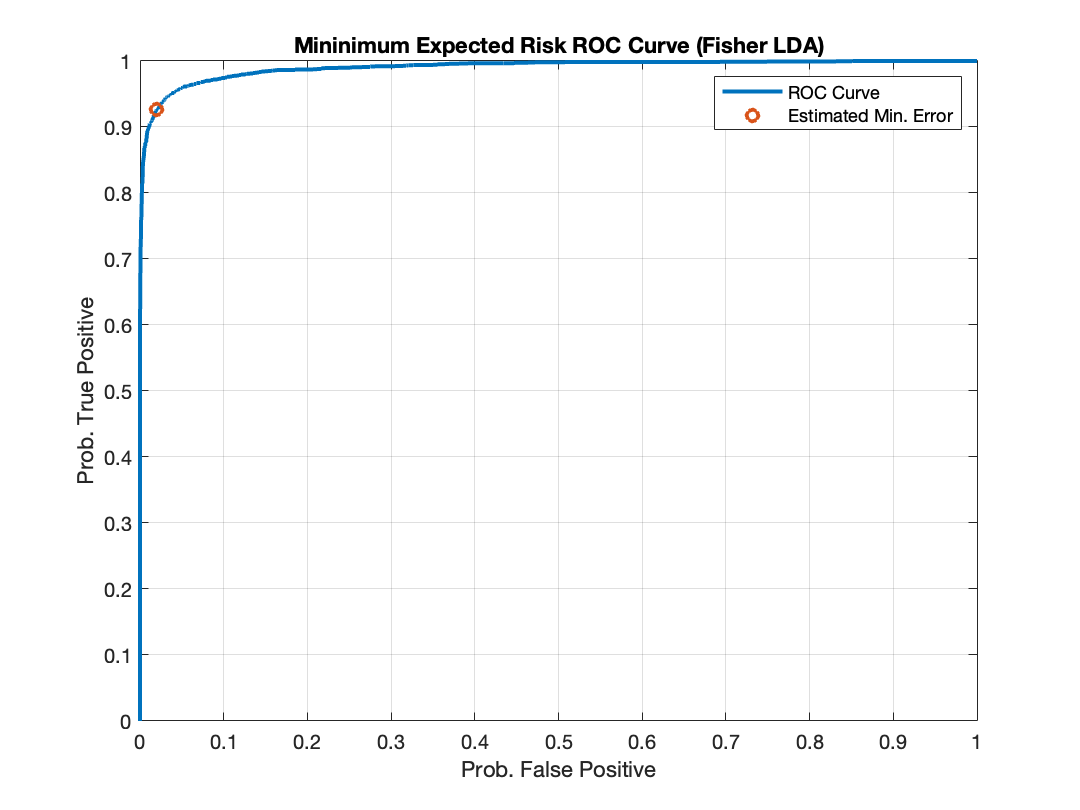


figure;
plot(pFP_LDA,pTP_LDA,'DisplayName','ROC Curve','LineWidth',2); 
hold all;
plot(min_FP_LDA,min_TP_LDA,'o','DisplayName',...
    'Estimated Min. Error','LineWidth',2); 
xlabel('Prob. False Positive'); 
ylabel('Prob. True Positive'); 
title('Mininimum Expected Risk ROC Curve (Fisher LDA)'); 
legend 'show';
grid on; 
box on;

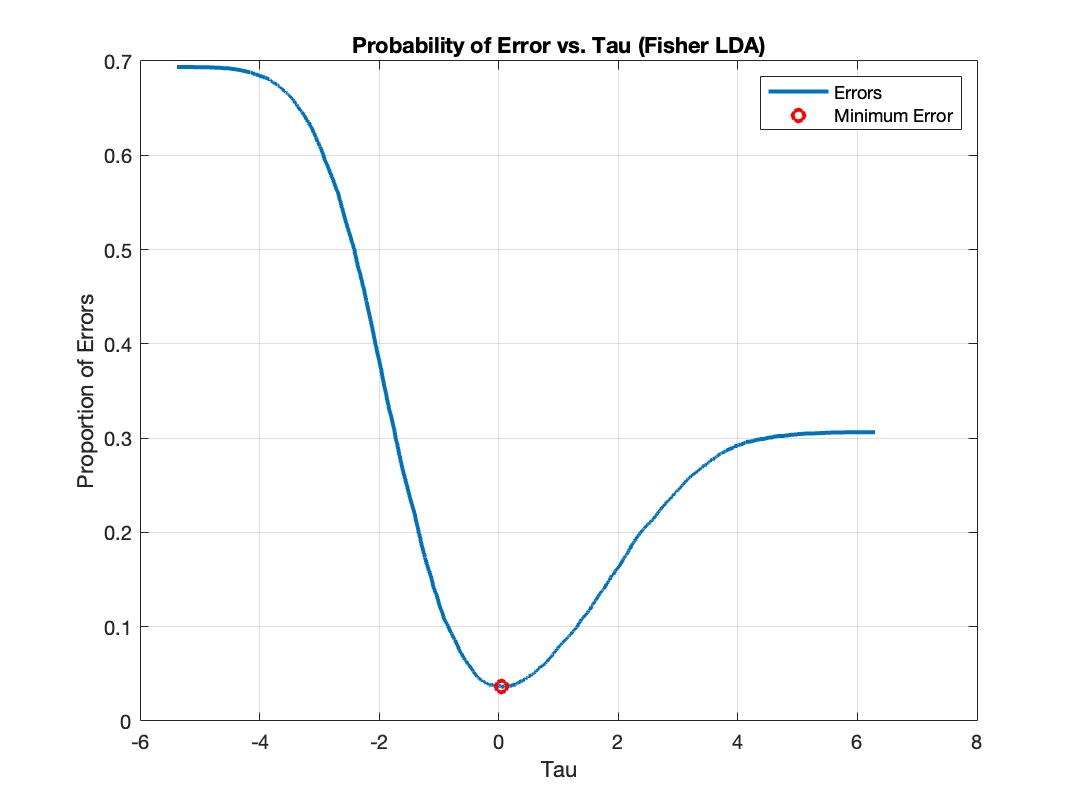


figure; 
plot(tau,pFE_LDA,'DisplayName','Errors','LineWidth',2); 
hold on; 
plot(tau(min_pFE_ind_LDA),pFE_LDA(min_pFE_ind_LDA),'ro',...
    'DisplayName','Minimum Error','LineWidth',2); 
xlabel('Tau');
ylabel('Proportion of Errors');
title('Probability of Error vs. Tau (Fisher LDA)')

grid on;
legend 'show';

fprintf('Estimated for LDA: Tau=%1.2f, Error=%1.2f%%\n', minTAU_LDA,100*min_pFE_LDA);

Estimated for LDA: Tau=0.05, Error=3.63%


function g = evalGaussian(x ,mu,Sigma)
%Evaluates the Gaussian pdf N(mu, Sigma ) at each column of X
[n,N] = size(x);
C = ((2*pi)^n * det(Sigma))^(-1/2); %coefficient
E = -0.5*sum((x-repmat(mu,1,N)).*(inv(Sigma)*(x-repmat(mu,1,N))),1);%exponent 
g = C*exp(E); %finalgaussianevaluation
end
